# Jリーグのシーズン予測

clear;clc;close all;
load predictionModel_JLeague.mat mdl r

データの読み込みと前処理

tbl_results=readtable('../../data/JLeagueResults.xlsx');
tbl_results.Category=categorical(tbl_results.Category);
tbl_results.HomeJ=categorical(tbl_results.HomeJ);
tbl_results.HomeE=categorical(tbl_results.HomeE);
tbl_results.AwayJ=categorical(tbl_results.AwayJ);
tbl_results.AwayE=categorical(tbl_results.AwayE);

ind = tbl_results.Year==2023 ...
    & (tbl_results.Category=='Ｊ１' ...
    | tbl_results.Category=='Ｊ２' ...
    | tbl_results.Category=='Ｊ３');
tbl_results=tbl_results(ind,:)

tbl_results = 1148×15 table
    MatchID    Year    Category       Date           KickoffTime        HomeJ       HomeE       AwayJ       AwayE       HomeGoals    AwayGoals    HomePKs    AwayPKs      Stadium      Attendance
    _______    ____    ________    __________    ___________________    ______    __________    ______    __________    _________    _________    _______    _______    ___________    __________

     28163     2023      Ｊ１      2023/02/17    2023/02/17 19:04:00    川崎Ｆ     kawasakif     横浜FM     yokohamafm        1            2          NaN        NaN      {'等々力'  }      22563   
     28165     2023      Ｊ１      2023/02/18    2023/02/18 14:03:00    横浜FC     yokohamafc    名古屋     nagoya            0            1          NaN        NaN      {'ニッパツ'}       11186   
     28166     2023      Ｊ１      2023/02/18    2023/02/18 14:03:00    京都       kyoto         鹿島       kashima           0            2          NaN        NaN      {'サンガＳ'}      15988   
     28169     2023   

teamNames=unique([tbl_results.HomeE;tbl_results.AwayE])

teamNames = 60×1 の categorical 配列
     akita 
     chiba 
     cosaka 
     ehime 
     fosaka 
     ftokyo 
     fujieda 
     fukuoka 
     fukushima 
     gifu 
     gosaka 
     hachinohe 
     hiroshima 
     imabari 
     iwaki 
     iwata 
     kagoshima 
     kanazawa 
     kashima 
     kashiwa 
     kawasakif 
     kitakyushu 
     kobe 
     kofu 
     kumamoto 
     kusatsu 
     kyoto 
     machida 
     matsumoto 
     mito 


teamNamesJ=[];
for n1=1:size(teamNames,1)
    ind = tbl_results.HomeE==teamNames(n1);
    teamNamesJ=[teamNamesJ;unique(tbl_results.HomeJ(ind))];
end


各カテゴリのチーム番号・チーム名

ind=tbl_results.Category=='Ｊ１';
J1TeamNames=unique([tbl_results.HomeE(ind) tbl_results.AwayE(ind)]);
J1TeamNums=find(ismember(teamNames,J1TeamNames));
J1TeamNamesJ=teamNamesJ(J1TeamNums);

ind=tbl_results.Category=='Ｊ２';
J2TeamNames=unique([tbl_results.HomeE(ind) tbl_results.AwayE(ind)]);
J2TeamNums=find(ismember(teamNames,J2TeamNames));

ind=tbl_results.Category=='Ｊ３';
J3TeamNames=unique([tbl_results.HomeE(ind) tbl_results.AwayE(ind)]);
J3TeamNums=find(ismember(teamNames,J3TeamNames));

シミュレーションの回数(シーズン数)の設定

Opt.nSeasons=1000;

チーム名，得点を数値配列としておく(この後の高速化のため)

teamNums=zeros(size(tbl_results,1),2);
for n1=1:size(teamNames,1)
    ind_home=tbl_results.HomeE==teamNames(n1);
    ind_away=tbl_results.AwayE==teamNames(n1);
    teamNums(ind_home,1)=n1;
    teamNums(ind_away,2)=n1;
end

goalVals=[tbl_results.HomeGoals tbl_results.AwayGoals];

予測実施日(レーティング算出日)を決定し，その日以降の試合を予測モデルに基づきシミュレーションする

predictionDate=datetime(2023,6,1);

ind = tbl_results.Date<=predictionDate;
tbl_train=tbl_results(ind,:);
tbl_upcoming=tbl_results(~ind,:);
teamNums_train=teamNums(ind,:);
goalVals_train=goalVals(ind,:);
teamNums_upcoming=teamNums(~ind,:); %未実施の試合の対戦チーム番号

レーティング算出

X=zeros(size(tbl_train,1),size(teamNames,1));
homeTeamNums=teamNums_train(ind,1);
awayTeamNums=teamNums_train(ind,2);
for n1=1:size(X,1)
    X(n1,homeTeamNums(n1))=1;
    X(n1,awayTeamNums(n1))=-1;
end
X=[X ones(sum(ind),1)];
b=log((goalVals_train(ind,1)+1)./(goalVals_train(ind,2)+1));

r=pinv(X)*b;

対戦時の予測勝点の算出

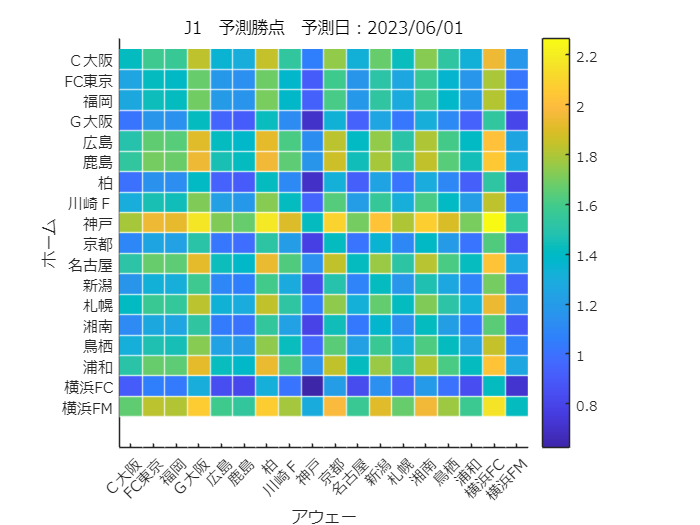

plotData=zeros(size(J1TeamNums,1));
for n1=1:size(J1TeamNums,1)
    for n2=1:size(J1TeamNums,1)
        taNum=J1TeamNums(n1);
        tbNum=J1TeamNums(n2);
        taRating=r(taNum);
        tbRating=r(tbNum);
        homeAdv=r(end);
        rateDiff=taRating-tbRating+homeAdv;
        pLose=glmval(mdl(1,:)', rateDiff,'logit');
        pWin=1-glmval(mdl(2,:)', rateDiff,'logit');
        exPoints=3*pWin+(1-pWin-pLose);
        plotData(n1,n2)=exPoints;
    end
end
figure
set(gca,'fontname','メイリオ');hold on;axis square;
imagesc(plotData);yticks(1:size(J1TeamNums,1));
set(gca,'ydir','reverse');
xlim([0.5 size(J1TeamNums,1)+0.5]);
xticks(1:size(J1TeamNums,1));
colormap("parula");colorbar;caxis([min(plotData,[],"all") max(plotData,[],"all")]);
for n1=1:size(J1TeamNums,1)
    xline(n1+0.5,'w');
    yline(n1+0.5,'w');
end
yticklabels(J1TeamNamesJ);
xticklabels(J1TeamNamesJ);
ylabel('ホーム');xlabel('アウェー');
title(['J1　予測勝点　予測日：' datestr(predictionDate,'yyyy/mm/dd')]);
exportgraphics(gcf,['fig_J1Prediction_ExpectedPoints_' datestr(predictionDate,'yyyymmdd') '.pdf']);

終了済み試合の集計

points_finished=zeros(size(teamNames,1),1);
goals_finished=zeros(size(teamNames,1),2);
for n1=1:size(teamNums_train,1)
    taNum=teamNums_train(n1,1);
    tbNum=teamNums_train(n1,2);
    goals_finished(taNum,1)=goals_finished(taNum,1)+goalVals_train(n1,1);
    goals_finished(tbNum,1)=goals_finished(tbNum,1)+goalVals_train(n1,2);
    goals_finished(taNum,2)=goals_finished(taNum,2)+goalVals_train(n1,2);
    goals_finished(tbNum,2)=goals_finished(tbNum,2)+goalVals_train(n1,1);

    if goalVals_train(n1,1)>goalVals_train(n1,2)
        % ホーム勝利
        points_finished(taNum)=points_finished(taNum)+3;
    elseif goalVals_train(n1,1)==goalVals_train(n1,2)
        points_finished(taNum)=points_finished(taNum)+1;
        points_finished(tbNum)=points_finished(tbNum)+1;
    else
        points_finished(tbNum)=points_finished(tbNum)+3;
    end
end


未消化試合の予測勝率など

rateDiff_upcoming=zeros(size(teamNums_upcoming,1),1);
p_upcoming=zeros(size(teamNums_upcoming,1),2);
for n1=1:size(p_upcoming,1)
    taNum=teamNums_upcoming(n1,1);
    tbNum=teamNums_upcoming(n1,2);
    taRating=r(taNum);
    tbRating=r(tbNum);
    homeAdv=r(end);
    rateDiff_upcoming(n1)=taRating-tbRating+homeAdv;
    p_upcoming(n1,1)=glmval(mdl(1,:)',rateDiff_upcoming(n1),'logit');
    p_upcoming(n1,2)=glmval(mdl(2,:)',rateDiff_upcoming(n1),'logit');
end

シーズンのシミュレーション

points=zeros(size(teamNames,1),Opt.nSeasons);
standings=zeros(size(teamNames,1),Opt.nSeasons);
for k=1:Opt.nSeasons
    points(:,k)=points_finished + 0.001*(goals_finished(:,1)-goals_finished(:,2));
    for n1=1:size(tbl_upcoming,1)
        randVal=rand();
        taNum=teamNums_upcoming(n1,1);
        tbNum=teamNums_upcoming(n1,2);

        if randVal< p_upcoming(n1,1)
            % ホーム負け
            points(tbNum,k)=points(tbNum,k)+3+rand()*0.0001;
        elseif randVal< p_upcoming(n1,2)
            % 引き分け
            points(taNum,k)=points(taNum,k)+1;
            points(tbNum,k)=points(tbNum,k)+1;
        else
            % ホーム勝ち
            points(taNum,k)=points(taNum,k)+3+rand()*0.0001;

        end
    end
end

リーグごとに集計


[val,ind]=sort(points(J1TeamNums,:),1,"descend");
for n1=1:size(standings,2)
    for n2=1:size(J1TeamNums,1)
        standings(J1TeamNums(ind(n2,n1)),n1)=n2;
    end
end

[val,ind]=sort(points(J2TeamNums,:),1,"descend");
for n1=1:size(standings,2)
    for n2=1:size(J2TeamNums,1)
        standings(J2TeamNums(ind(n2,n1)),n1)=n2;
    end
end

[val,ind]=sort(points(J3TeamNums,:),1,"descend");
for n1=1:size(standings,2)
    for n2=1:size(J3TeamNums,1)
        standings(J3TeamNums(ind(n2,n1)),n1)=n2;
    end
end

順位の図示

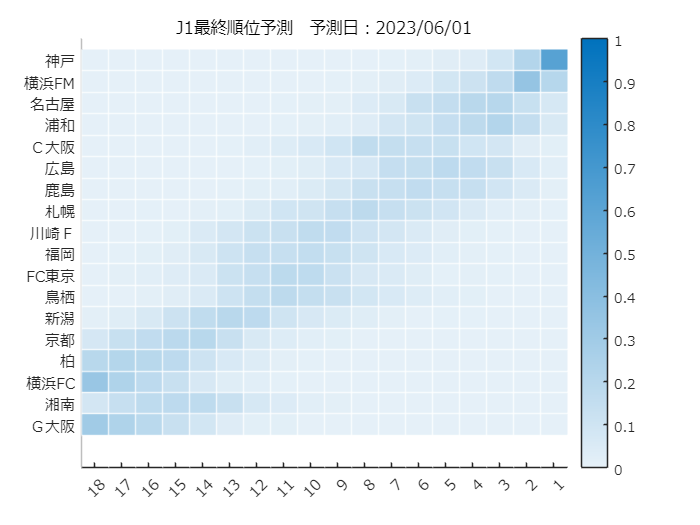

points_finished_tmp=points_finished+0.001*(goals_finished(:,1)-goals_finished(:,2));

[~,ind_curSt]=sort(points_finished_tmp(J1TeamNums),'descend');
st_J1= standings(J1TeamNums,:);
stCounts=zeros(size(J1TeamNums,1));
for n1=1:size(stCounts,1)
    stCounts(n1,:)=histcounts(st_J1(n1,:),(0:size(J1TeamNums,1))+0.5);
end
figure
set(gca,'fontname','メイリオ');hold on;
imagesc(stCounts(ind_curSt,:)/Opt.nSeasons);
yticks(1:size(J1TeamNums,1));
yticklabels(J1TeamNamesJ(ind_curSt));
set(gca,'xdir','reverse','ydir','reverse');
xlim([0.5 size(J1TeamNums,1)+0.5]);
xticks(1:size(J1TeamNums,1));
colormap(sky);colorbar;caxis([0 1]);
for n1=1:size(J1TeamNums,1)
    xline(n1+0.5,'w');
    yline(n1+0.5,'w');
end
title(['J1最終順位予測　予測日：' datestr(predictionDate,'yyyy/mm/dd')]);
exportgraphics(gcf,['fig_J1Prediction_FinalStandings_' datestr(predictionDate,'yyyymmdd') '.pdf']);

勝点分布

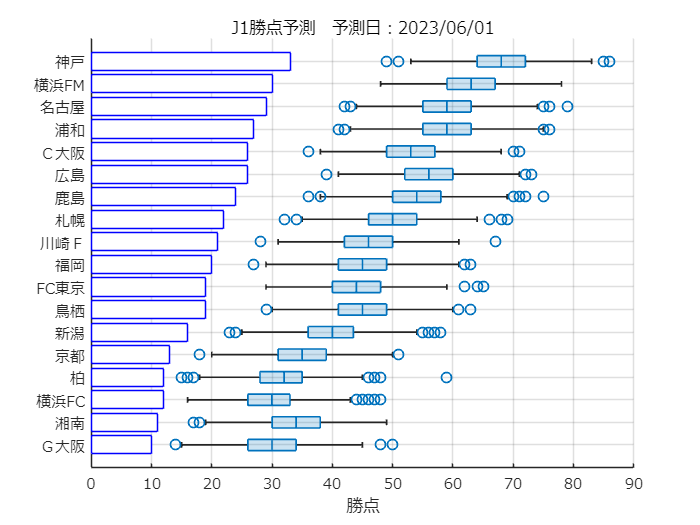

figure;hold on;grid on;set(gca,'fontname','メイリオ');
boxchart(points(J1TeamNums(ind_curSt),:)','Orientation','horizontal');
barh(points_finished(J1TeamNums(ind_curSt)),'FaceColor','w','EdgeColor','b');
xlim([0 90])
set(gca,'ydir','reverse');yticklabels(J1TeamNamesJ(ind_curSt));
title(['J1勝点予測　予測日：' datestr(predictionDate,'yyyy/mm/dd')]);
xlabel('勝点');

exportgraphics(gcf,['fig_J1Prediction_FinalPoints_' datestr(predictionDate,'yyyymmdd') '.pdf']);

結果との比較

pLose=p_upcoming(:,1);  %ホーム負け確率
pDraw=p_upcoming(:,2)-p_upcoming(:,1);  %ホーム引き分け確率
pWin=1-p_upcoming(:,2); %ホーム勝利確率
goalDiffs=tbl_upcoming.HomeGoals-tbl_upcoming.AwayGoals;

bins=0:0.05:1;
hCounts=[]; %各階級の度数
ind_win=goalDiffs>0;
ind_draw=goalDiffs==0;
ind_lose=goalDiffs<0;

p=pWin+pDraw/2;
hCounts=[histcounts(p(ind_lose),bins);
    histcounts(p(ind_draw),bins);
    histcounts(p(ind_win),bins)]

hCounts =      0     0     0     0     0     1     6    24    45    54    43    35    27     7     1     0     0     0     0     0
     0     0     0     0     0     0     7    16    24    40    40    32    20    13     3     1     0     0     0     0
     0     0     0     0     1     1     3    14    29    46    55    50    45    18     5     0     0     0     0     0


較正値

ind_s=p>0.5;    %予測上位かどうか
aWins=sum(ind_win(ind_s))+sum(ind_draw)*0.5+sum(ind_lose(~ind_s));

aWins = 401

pSum=sum(p(ind_s))+sum(1-p(~ind_s))

pSum = 406.0606

calibVal=pSum/aWins

calibVal = 1.0126

頻度と割合の図示

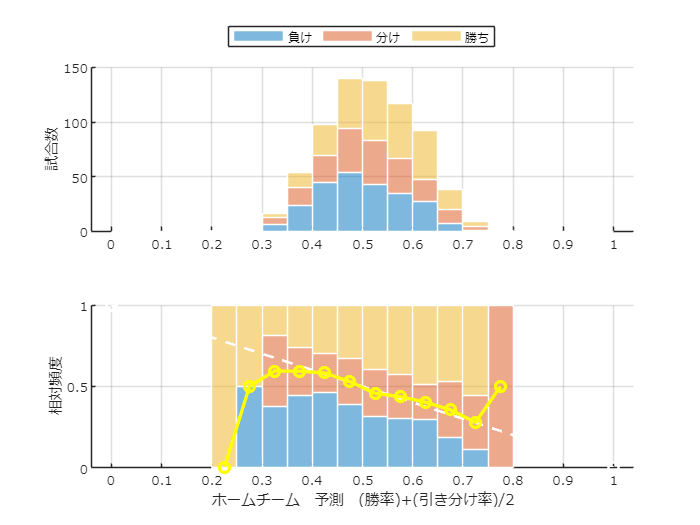

aRatio=1-(hCounts(3,:)+1/2*hCounts(2,:))./sum(hCounts);
figure
tiledlayout(2,1);
nexttile;set(gca,'fontname','メイリオ');grid on;hold on;
set(gca,'fontname','メイリオ');

bObj=bar(movmean(bins,2,'Endpoints','discard'), hCounts,'stacked', ...
    'EdgeColor','w','BarWidth',1);
ylabel('試合数');
bObj(1).FaceAlpha=0.5;
bObj(2).FaceAlpha=0.5;
bObj(3).FaceAlpha=0.5;
legend({'負け','分け','勝ち'},'Location','northoutside','Orientation','horizontal');
ylabel('試合数');

nexttile;
set(gca,'fontname','メイリオ');grid on;hold on;
set(gca,'fontname','メイリオ');
bObj=bar(movmean(bins,2,'Endpoints','discard'), ...
    hCounts./sum(hCounts,1),'stacked', ...
    'EdgeColor','w','BarWidth',1);
bObj(1).FaceAlpha=0.5;
bObj(2).FaceAlpha=0.5;
bObj(3).FaceAlpha=0.5;
plot([0 1],[1 0],'ow--','LineWidth',1.5);
plot(movmean(bins,2,'Endpoints','discard'),aRatio,'yo-','LineWidth',2)
xlabel('ホームチーム　予測　(勝率)+(引き分け率)/2');
ylabel('相対頻度');
exportgraphics(gcf,['fig_J1PredictionPerformance_' datestr(predictionDate,'yyyymmdd') '.pdf']);